## Load Training Data

Do not edit

Load the clothing training dataset. Please download the data from the module website Then, unzip the downloaded files and put in the current directory. Make this working the working directory for MATLAB.

After unzipping the files, you should find the four files entitled train-images-idx3-ubyte, train-labels-idx1-ubyte, t10k-images-idx3-ubyte and t10k-labels-idx1-ubyte.

clear;clc;close all force
TrainimageFileName = 'train-images-idx3-ubyte';
TrainlabelFileName = 'train-labels-idx1-ubyte';
TestimageFileName = 't10k-images-idx3-ubyte';
TestlabelFileName = 't10k-labels-idx1-ubyte';

Process the downloaded images and labels using the helper function. 

[XTrain,YTrain] = processclothingdata(TrainimageFileName,TrainlabelFileName);


Read image data...
Number of images in the dataset:  60000 ...
Each image is of 28 by 28 pixels...
The image data is read to a matrix of dimensions:     28 by   28...
End of reading image data.

Read corresponding image class label data...
Number of labels in the dataset:  60000 ...
The label data is read to a matrix of dimensions:  60000 by  1...
End of reading label data.


[XTest,YTest] = processclothingdata(TestimageFileName,TestlabelFileName);


Read image data...
Number of images in the dataset:  10000 ...
Each image is of 28 by 28 pixels...
The image data is read to a matrix of dimensions:     28 by   28...
End of reading image data.

Read corresponding image class label data...
Number of labels in the dataset:  10000 ...
The label data is read to a matrix of dimensions:  10000 by  1...
End of reading label data.


numTrain=size(XTrain,4)

numTrain = 60000

Please confirm that the necessary variables are sucessfully generated in the workspace.

## Store the data into image data store (Table 1)

Do not edit

The function `imageDataAugmenter` is for configuring data augmentation as a training preprocessing step. It is capable of performing a various pre-processing options such as rotation, translation, and resizing. For example, if you perform a randomized rotation to the training images, the network is expected to be invariant to the rotation. If you need more advanced oparation, please use` transform `function to perform the augmentation before network training.

% % no code changes necessary
% imageAugmenter = imageDataAugmenter( )
% 
% % the input size for the network
% % The image size to input should match the input size for network
% imageSize = [28 28 1];
% % set the augmented image data store to provide a batch of augmented images
% augimds = augmentedImageDatastore(imageSize,XTrain,categorical(YTrain),'DataAugmentation',imageAugmenter,'OutputSizeMode',"resize");

## Store the data into image data store (Group solution Table 3 and 4)

The function `imageDataAugmenter` is for configuring data augmentation as a training preprocessing step. It is capable of performing a various pre-processing options such as rotation, translation, and resizing. For example, if you perform a randomized rotation to the training images, the network is expected to be invariant to the rotation. If you need more advanced oparation, please use` transform `function to perform the augmentation before network training. See [here](https://blogs.mathworks.com/deep-learning/2019/08/22/data-augmentation-for-image-classification-applications-using-deep-learning/?doing_wp_cron=1644513533.1656401157379150390625)  

imageAugmenter = imageDataAugmenter( ...
    'RandRotation', [-5 5], ...
    'RandXTranslation', [-2 2], ...
    'RandYTranslation', [-2 2], ...
    'RandXReflection', false);
% the input size for the network
imageSize = [28 28 1];
% set the augmented image data store to provide a batch of augmented images
augimds = augmentedImageDatastore(imageSize,XTrain,categorical(YTrain), ...
    'DataAugmentation',imageAugmenter,'OutputSizeMode',"resize");

## Randomly display images

Do not edit

Display some example of images.

% specify the number of images to display
numEx=64;
% the randperm function returns a randomized permutation of integers
idx=randperm(numTrain,numEx);
% read images from augmented data store by index
ImgEx=readByIndex(augimds,idx);
% loop over the index
for i=1:numEx
   Input=uint8(ImgEx.input{i});
   class=YTrain{idx(i)};
   % insert label information to the image
   I{i}=insertText(Input,[1 1],class,'FontSize',7);    
end
figure;montage(I)

## Define layers (Group solution Tables 1, 2 and 3)

The network consists of 15 layers. You can define each layer easily such as with `convolution2dLayer`.  For the detail, please check the comment below. See [here](https://uk.mathworks.com/help/deeplearning/ug/list-of-deep-learning-layers.html) 

% layers = [
%     % image input layer whose input size is 28-28-1. "1" represents one
%     % color channel (gray scale image)
%     imageInputLayer([28 28 1]) 
% 
%     % add additional Layers here
%     % ===== CONV_1 BLOCK =====
%     convolution2dLayer(3, 8, "Padding","same", "Name","conv1")
%     batchNormalizationLayer("Name","bn1")
%     reluLayer("Name","relu1")
% 
%     maxPooling2dLayer(2, "Stride",2, "Name","pool1")
% 
%     % ===== CONV_2 BLOCK =====
%     convolution2dLayer(3, 16, "Padding","same", "Name","conv2")
%     batchNormalizationLayer("Name","bn2")
%     reluLayer("Name","relu2")
% 
%     maxPooling2dLayer(2, "Stride",2, "Name","pool2")
% 
%     % ===== CONV_3 BLOCK =====
%     convolution2dLayer(3, 32, "Padding","same", "Name","conv3")
%     batchNormalizationLayer("Name","bn3")
%     reluLayer("Name","relu3")
%     % output size 7×7×32
% 
%     % ===== FINAL FC =====
%     fullyConnectedLayer(10, "Name","fc8")
%     softmaxLayer("Name","softmax")
%     classificationLayer("Name","classoutput")
%     ];
% % analyze the network architecture using analyzeNetwork function
% analyzeNetwork(layers);

## Specify training options (Group Solution Table 1 and 2)

Specify the training options here. Use the training options as an input argment in next section. 

For the detail, please check [here](https://jp.mathworks.com/help/deeplearning/ref/trainingoptions.html?lang=en). 

% options = trainingOptions('sgdm', ...
%     'InitialLearnRate', 0.01);

## Specify training options (Group Solution Table 3 and 4)

Specify the training options here. Use the training options as an input argment in next section. 

For the detail, please check [here](https://jp.mathworks.com/help/deeplearning/ref/trainingoptions.html?lang=en). 

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.01, ...        
    'MiniBatchSize', 256, ...
    'MaxEpochs', 25, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XTest, categorical(YTest)}, ...
    'ValidationFrequency', 50, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.2, ...
    'LearnRateDropPeriod',7, ...
    'L2Regularization', 0.0005, ...
    'GradientThreshold', 2, ...
    'ExecutionEnvironment','auto', ...
    'Plots','training-progress', ...
    'Verbose',true);

## Group Member #1 Enio

## Define layers (Individual Solution Table 4)

The network consists of maximum 25 layers. You can define each layer easily such as with `convolution2dLayer`.  For the detail, please check the comment below. 

layers = [
    % Input
    imageInputLayer([28 28 1], 'Name', 'input')


    convolution2dLayer(3, 32, 'Padding', 'same', 'Name', 'conv_1') 
    batchNormalizationLayer('Name', 'bn_1')
    reluLayer('Name', 'relu_1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool_1')


    convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'conv_2') 
    batchNormalizationLayer('Name', 'bn_2')
    reluLayer('Name', 'relu_2')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool_2')


    convolution2dLayer(3, 128, 'Padding', 'same', 'Name', 'conv_3') 
    batchNormalizationLayer('Name', 'bn_3')
    reluLayer('Name', 'relu_3')


    % --- Regularization (droput layer)
    dropoutLayer(0.4, 'Name', 'dropout')

    % --- Output ---
    fullyConnectedLayer(10, 'Name', 'fc')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'output')
];

% analyze the network architecture using analyzeNetwork function
analyzeNetwork(layers)

Add your own code to predict the clothing category of your downloaded 10 clothing images. [Hint: load your images into a image datastore, use image datastore augmenter to resize the images and convert to grayscale and classify function to generate the network predictions.]

% %Detect the training scale
% if exist('XTrain','var')
%     trainMax = max(double(XTrain), [], 'all');
% else
%     trainMax = 255;
% end
% %load the images from the folder MyClothingImages 
% folderPath = 'EnioClothingImages';
% imds_web = imageDatastore(folderPath, 'FileExtensions', {'.jpg','.png','.jpeg'});
% data = readall(imds_web);
% numImages = length(data);
% 
% %preallocate the output
% if trainMax <= 1
%     processed_batch = zeros(28,28,1,numImages);   % double 0–1
% else
%     processed_batch = uint8(zeros(28,28,1,numImages)); % uint8 0–255
% end
% 
% predictedLabels = strings(numImages,1);
% 
% %adjusting the images to fit the network's training style
% for i = 1:numImages
% 
%     % resize + grayscale
%     img = imresize(data{i}, [28 28]);
%     if size(img,3) == 3
%         img = rgb2gray(img);
%     end
%     img = double(img);
% 
%     %if a white background is detected it will be automatically inverted
%     if mean(img,'all') > 128
%         img = 255 - img;
%     end
% 
%     %remove any low value noisy like shadows
%     img(img < 50) = 0;
% 
%     %test time augmentation checks between flipped image and the original
%     img_normal = img;
%     img_flip   = fliplr(img);
% 
%     mini_batch = cat(4, img_normal, img_flip);
% 
% 
%     if trainMax <= 1
%         mini_batch = mini_batch / 255.0;
%     end
% 
%     %classify both versions of the image
%     [preds, scores] = classify(net, mini_batch);
% 
%     %prompt the network to pick the one with higher confidence
%     [~, bestIdx] = max(max(scores,[],2));
%     predictedLabels(i) = string(preds(bestIdx));
% 
%     % save the image to display
%     if trainMax <= 1
%         processed_batch(:,:,1,i) = mini_batch(:,:,1,bestIdx);
%     else
%         processed_batch(:,:,1,i) = uint8(mini_batch(:,:,1,bestIdx));
%     end
% end
% 
% %display the results
% figure('Name','Advanced Prediction Results (TTA)');
% for i = 1:numImages
%     subplot(2,5,i);
%     imshow(processed_batch(:,:,1,i));
%     title(predictedLabels(i));
% end

## Group Member #2 Ankit

## Define layers (Individual Solution Table 4)

The network consists of maximum 25 layers. You can define each layer easily such as with `convolution2dLayer`.  For the detail, please check the comment below. 

% layers = [
%     % 1. Input Layer
%     imageInputLayer([28 28 1], 'Name', 'input')
% 
%     % Block 1: Detailed Feature Extraction (Edges/Textures)
%     convolution2dLayer(3, 32, 'Padding', 'same', 'Name', 'conv_1_1')
%     batchNormalizationLayer('Name', 'bn_1_1')
%     reluLayer('Name', 'relu_1_1')
% 
%     convolution2dLayer(3, 32, 'Padding', 'same', 'Name', 'conv_1_2')
%     batchNormalizationLayer('Name', 'bn_1_2')
%     reluLayer('Name', 'relu_1_2')
% 
%     maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool_1') % Downsample to 14x14
% 
%     % Block 2: Shape Feature Extraction (Loops, Handles, Sleeves)
%     convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'conv_2_1')
%     batchNormalizationLayer('Name', 'bn_2_1')
%     reluLayer('Name', 'relu_2_1')
% 
%     convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'conv_2_2')
%     batchNormalizationLayer('Name', 'bn_2_2')
%     reluLayer('Name', 'relu_2_2')
% 
%     maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool_2') % Downsample to 7x7
% 
%     % Classifier Block
%     fullyConnectedLayer(512, 'Name', 'fc_1') % Increased to 512 for better capacity
%     batchNormalizationLayer('Name', 'bn_fc')
%     reluLayer('Name', 'relu_fc')
%     dropoutLayer(0.5, 'Name', 'dropout')     % 50% Dropout is critical for 94%
% 
%     fullyConnectedLayer(10, 'Name', 'fc_out')
%     softmaxLayer('Name', 'softmax')
%     classificationLayer('Name', 'classoutput')
% ];
% % analyze the network architecture using analyzeNetwork function
% analyzeNetwork(layers)

Add your own code to predict the clothing category of your downloaded 10 clothing images. [Hint: load your images into a image datastore, use image datastore augmenter to resize the images and convert to grayscale and classify function to generate the network predictions.]

% %Detect the training scale
% if exist('XTrain','var')
%     trainMax = max(double(XTrain), [], 'all');
% else
%     trainMax = 255;
% end
% %load the images from the folder MyClothingImages 
% folderPath = 'AnkitClothingImages';
% imds_web = imageDatastore(folderPath, 'FileExtensions', {'.jpg','.png','.jpeg'});
% data = readall(imds_web);
% numImages = length(data);
% 
% %preallocate the output
% if trainMax <= 1
%     processed_batch = zeros(28,28,1,numImages);   % double 0–1
% else
%     processed_batch = uint8(zeros(28,28,1,numImages)); % uint8 0–255
% end
% 
% predictedLabels = strings(numImages,1);
% 
% %adjusting the images to fit the network's training style
% for i = 1:numImages
% 
%     % resize + grayscale
%     img = imresize(data{i}, [28 28]);
%     if size(img,3) == 3
%         img = rgb2gray(img);
%     end
%     img = double(img);
% 
%     %if a white background is detected it will be automatically inverted
%     if mean(img,'all') > 128
%         img = 255 - img;
%     end
% 
%     %remove any low value noisy like shadows
%     img(img < 50) = 0;
% 
%     %test time augmentation checks between flipped image and the original
%     img_normal = img;
%     img_flip   = fliplr(img);
% 
%     mini_batch = cat(4, img_normal, img_flip);
% 
% 
%     if trainMax <= 1
%         mini_batch = mini_batch / 255.0;
%     end
% 
%     %classify both versions of the image
%     [preds, scores] = classify(net, mini_batch);
% 
%     %prompt the network to pick the one with higher confidence
%     [~, bestIdx] = max(max(scores,[],2));
%     predictedLabels(i) = string(preds(bestIdx));
% 
%     % save the image to display
%     if trainMax <= 1
%         processed_batch(:,:,1,i) = mini_batch(:,:,1,bestIdx);
%     else
%         processed_batch(:,:,1,i) = uint8(mini_batch(:,:,1,bestIdx));
%     end
% end
% 
% %display the results
% figure('Name','Advanced Prediction Results (TTA)');
% for i = 1:numImages
%     subplot(2,5,i);
%     imshow(processed_batch(:,:,1,i));
%     title(predictedLabels(i));
% end

## Group Member #3 Kai

## Define layers (Individual Solution Table 4)

The network consists of maximum 25 layers. You can define each layer easily such as with `convolution2dLayer`.  For the detail, please check the comment below. 

% layers = [
%     imageInputLayer([28 28 1],'Name','input')
% 
%     % Block 1
%     convolution2dLayer(3,64,'Padding','same','Name','conv1_1')
%     batchNormalizationLayer('Name','bn1_1')
%     reluLayer('Name','relu1_1')
% 
%     convolution2dLayer(3,64,'Padding','same','Name','conv1_2')
%     batchNormalizationLayer('Name','bn1_2')
%     reluLayer('Name','relu1_2')
% 
%     maxPooling2dLayer(2,'Stride',2,'Name','pool1')
% 
%     % Block 2
%     convolution2dLayer(3,128,'Padding','same','Name','conv2_1')
%     batchNormalizationLayer('Name','bn2_1')
%     reluLayer('Name','relu2_1')
% 
%     convolution2dLayer(3,128,'Padding','same','Name','conv2_2')
%     batchNormalizationLayer('Name','bn2_2')
%     reluLayer('Name','relu2_2')
% 
%     maxPooling2dLayer(2,'Stride',2,'Name','pool2')
% 
%     % Block 3
%     convolution2dLayer(3,256,'Padding','same','Name','conv3_1')
%     batchNormalizationLayer('Name','bn3_1')
%     reluLayer('Name','relu3_1')
% 
%     % FC + Classifier
%     fullyConnectedLayer(256,'Name','fc1')
%     reluLayer('Name','relu_fc1')
% 
%     fullyConnectedLayer(10,'Name','fc2')
%     softmaxLayer('Name','softmax')
%     classificationLayer('Name','clsoutput')
% ];
% % analyze the network architecture using analyzeNetwork function
% analyzeNetwork(layers)

Add your own code to predict the clothing category of your downloaded 10 clothing images. [Hint: load your images into a image datastore, use image datastore augmenter to resize the images and convert to grayscale and classify function to generate the network predictions.]

% %Detect the training scale
% if exist('XTrain','var')
%     trainMax = max(double(XTrain), [], 'all');
% else
%     trainMax = 255;
% end
% %load the images from the folder MyClothingImages 
% folderPath = 'KaiClothingImages';
% imds_web = imageDatastore(folderPath, 'FileExtensions', {'.jpg','.png','.jpeg'});
% data = readall(imds_web);
% numImages = length(data);
% 
% %preallocate the output
% if trainMax <= 1
%     processed_batch = zeros(28,28,1,numImages);   % double 0–1
% else
%     processed_batch = uint8(zeros(28,28,1,numImages)); % uint8 0–255
% end
% 
% predictedLabels = strings(numImages,1);
% 
% %adjusting the images to fit the network's training style
% for i = 1:numImages
% 
%     % resize + grayscale
%     img = imresize(data{i}, [28 28]);
%     if size(img,3) == 3
%         img = rgb2gray(img);
%     end
%     img = double(img);
% 
%     %if a white background is detected it will be automatically inverted
%     if mean(img,'all') > 128
%         img = 255 - img;
%     end
% 
%     %remove any low value noisy like shadows
%     img(img < 50) = 0;
% 
%     %test time augmentation checks between flipped image and the original
%     img_normal = img;
%     img_flip   = fliplr(img);
% 
%     mini_batch = cat(4, img_normal, img_flip);
% 
% 
%     if trainMax <= 1
%         mini_batch = mini_batch / 255.0;
%     end
% 
%     %classify both versions of the image
%     [preds, scores] = classify(net, mini_batch);
% 
%     %prompt the network to pick the one with higher confidence
%     [~, bestIdx] = max(max(scores,[],2));
%     predictedLabels(i) = string(preds(bestIdx));
% 
%     % save the image to display
%     if trainMax <= 1
%         processed_batch(:,:,1,i) = mini_batch(:,:,1,bestIdx);
%     else
%         processed_batch(:,:,1,i) = uint8(mini_batch(:,:,1,bestIdx));
%     end
% end
% 
% %display the results
% figure('Name','Advanced Prediction Results (TTA)');
% for i = 1:numImages
%     subplot(2,5,i);
%     imshow(processed_batch(:,:,1,i));
%     title(predictedLabels(i));
% end

## Group Member #4 Adrian

## Define layers (Individual Solution Table 4)

The network consists of maximum 25 layers. You can define each layer easily such as with `convolution2dLayer`.  For the detail, please check the comment below. 

% layers = [
%     % --- Input Layer ---
%     imageInputLayer([28 28 1], 'Name', 'input')
% 
%     % --- Block 1: Basic Features ---
%     convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'ind_conv1')
%     batchNormalizationLayer('Name', 'ind_bn1')
%     reluLayer('Name', 'ind_relu1')
%     maxPooling2dLayer(2, 'Stride', 2, 'Name', 'ind_pool1') % 28 -> 14
% 
%     % --- Block 2: Intermediate Features ---
%     convolution2dLayer(3, 128, 'Padding', 'same', 'Name', 'ind_conv2')
%     batchNormalizationLayer('Name', 'ind_bn2')
%     reluLayer('Name', 'ind_relu2')
%     maxPooling2dLayer(2, 'Stride', 2, 'Name', 'ind_pool2') % 14 -> 7
% 
%     % --- Block 3: Advanced Features ---
%     convolution2dLayer(3, 256, 'Padding', 'same', 'Name', 'ind_conv3')
%     batchNormalizationLayer('Name', 'ind_bn3')
%     reluLayer('Name', 'ind_relu3')
%     % No pooling to keep 7x7 size
% 
%     % --- Block 4: Deep Semantic Features (Extra Block) ---
%     convolution2dLayer(3, 256, 'Padding', 'same', 'Name', 'ind_conv4')
%     batchNormalizationLayer('Name', 'ind_bn4')
%     reluLayer('Name', 'ind_relu4')
% 
%     % --- Classifier Block ---
%     fullyConnectedLayer(1024, 'Name', 'ind_fc1') % High Capacity
%     batchNormalizationLayer('Name', 'ind_bn_fc')
%     reluLayer('Name', 'ind_relu_fc')
%     dropoutLayer(0.25, 'Name', 'ind_dropout') % Balanced Dropout
% 
%     fullyConnectedLayer(10, 'Name', 'ind_fc_out')
%     softmaxLayer('Name', 'ind_softmax')
%     classificationLayer('Name', 'ind_classoutput')
%     ];
% 
% analyzeNetwork(layers)

Add your own code to predict the clothing category of your downloaded 10 clothing images. [Hint: load your images into a image datastore, use image datastore augmenter to resize the images and convert to grayscale and classify function to generate the network predictions.]

% %Detect the training scale
% if exist('XTrain','var')
%     trainMax = max(double(XTrain), [], 'all');
% else
%     trainMax = 255;
% end
% %load the images from the folder MyClothingImages 
% folderPath = 'AdrianClothingImages';
% imds_web = imageDatastore(folderPath, 'FileExtensions', {'.jpg','.png','.jpeg'});
% data = readall(imds_web);
% numImages = length(data);
% 
% %preallocate the output
% if trainMax <= 1
%     processed_batch = zeros(28,28,1,numImages);   % double 0–1
% else
%     processed_batch = uint8(zeros(28,28,1,numImages)); % uint8 0–255
% end
% 
% predictedLabels = strings(numImages,1);
% 
% %adjusting the images to fit the network's training style
% for i = 1:numImages
% 
%     % resize + grayscale
%     img = imresize(data{i}, [28 28]);
%     if size(img,3) == 3
%         img = rgb2gray(img);
%     end
%     img = double(img);
% 
%     %if a white background is detected it will be automatically inverted
%     if mean(img,'all') > 128
%         img = 255 - img;
%     end
% 
%     %remove any low value noisy like shadows
%     img(img < 50) = 0;
% 
%     %test time augmentation checks between flipped image and the original
%     img_normal = img;
%     img_flip   = fliplr(img);
% 
%     mini_batch = cat(4, img_normal, img_flip);
% 
% 
%     if trainMax <= 1
%         mini_batch = mini_batch / 255.0;
%     end
% 
%     %classify both versions of the image
%     [preds, scores] = classify(net, mini_batch);
% 
%     %prompt the network to pick the one with higher confidence
%     [~, bestIdx] = max(max(scores,[],2));
%     predictedLabels(i) = string(preds(bestIdx));
% 
%     % save the image to display
%     if trainMax <= 1
%         processed_batch(:,:,1,i) = mini_batch(:,:,1,bestIdx);
%     else
%         processed_batch(:,:,1,i) = uint8(mini_batch(:,:,1,bestIdx));
%     end
% end
% 
% %display the results
% figure('Name','Advanced Prediction Results (TTA)');
% for i = 1:numImages
%     subplot(2,5,i);
%     imshow(processed_batch(:,:,1,i));
%     title(predictedLabels(i));
% end

## Train network

Do not edit

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       12.50% |       33.70% |       2.8949 |       4.4965 |          0.0100 |
|       1 |          50 |       00:00:04 |       75.78% |       76.76% |       0.7046 |       0.6504 |          0.0100 |
|       1 |         100 |       00:00:07 |       80.86% |       80.65% |       0.5577 |       0.5081 |          0.0100 |
|       1 |         150 |       00:00:10 |       75.00% |       80.58% |       0.6777 |   

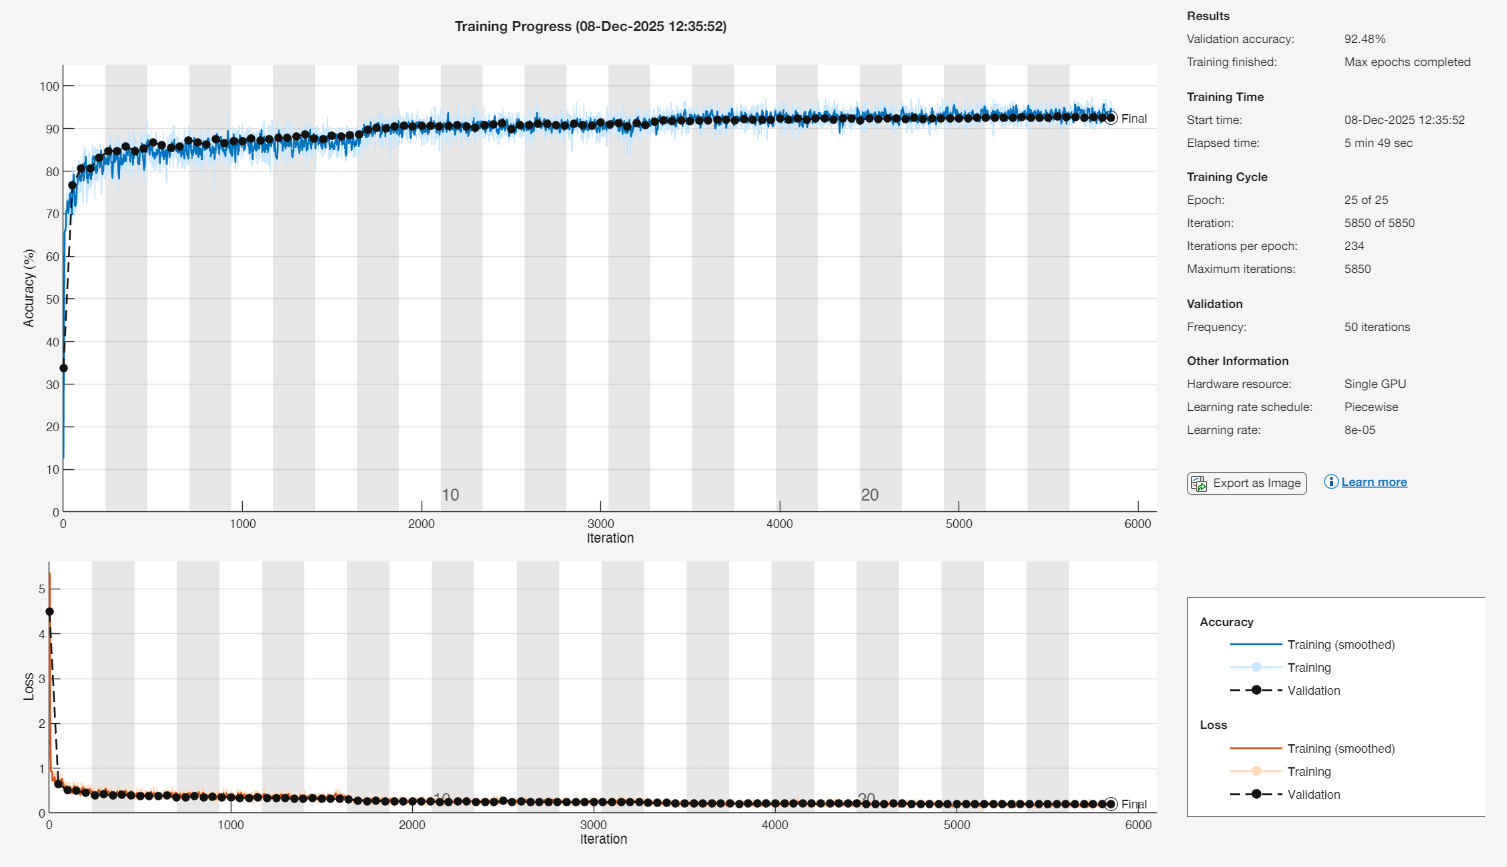

net = trainNetwork(augimds,layers,options);

## Accuracy assesment 

Do not edit

This section

- classifies the test images

- calculate the overall accuracy

- display the confusion matrix

% use classify function to classify the test data with the trained network
YPred = classify(net,XTest);
% YTest is the label information of the test data. 
YTest = categorical(YTest);
% if YPred (prediction result) and YTest (label data) is identical, it
% returns 1, otherwise, 0. Its sum/number of test data is the accuracy
accuracy = sum(YPred == YTest)/numel(YTest)

accuracy = 0.9248

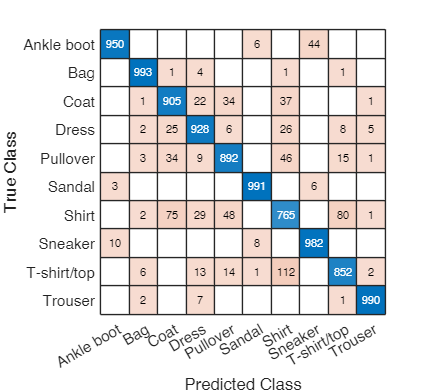

% create confusion matrix
confusionchart(YTest,YPred)

## Process clothing data in ubyte format

Do not edit

function [X,L_category] = processclothingdata(imageFileName,labelFileName)
class_names = {'T-shirt/top', 'Trouser', 'Pullover', 'Dress', 'Coat', ...
               'Sandal', 'Shirt', 'Sneaker', 'Bag', 'Ankle boot'};
[fileID,errmsg] = fopen(imageFileName,'r','b');
if fileID < 0
    error(errmsg);
end
%%
% First read the magic number. This number is 2051 for image data, and
% 2049 for label data
magicNum = fread(fileID,1,'int32',0,'b');
if magicNum == 2051
    fprintf('\nRead image data...\n')
end
%%
% Then read the number of images, number of rows, and number of columns
numImages = fread(fileID,1,'int32',0,'b');
fprintf('Number of images in the dataset: %6d ...\n',numImages);
numRows = fread(fileID,1,'int32',0,'b');
numCols = fread(fileID,1,'int32',0,'b');
fprintf('Each image is of %2d by %2d pixels...\n',numRows,numCols);
%%
% Read the image data
X = fread(fileID,inf,'unsigned char');
%%
% Reshape the data to array X
X = reshape(X,numCols,numRows,1,numImages);
X = permute(X,[2 1 3 4]);
%%
% Then flatten each image data into a 1 by (numRows*numCols) vector, and 
% store all the image data into a numImages by (numRows*numCols) array.
% X = reshape(X,numRows*numCols,numImages)';
fprintf(['The image data is read to a matrix of dimensions: %6d by %4d...\n',...
    'End of reading image data.\n'],size(X,1),size(X,2));
%%
% Close the file
fclose(fileID);
%%
% Similarly, read the label data.
[fileID,errmsg] = fopen(labelFileName,'r','b');
if fileID < 0
    error(errmsg);
end
magicNum = fread(fileID,1,'int32',0,'b');
if magicNum == 2049
    fprintf('\nRead corresponding image class label data...\n')
end
numItems = fread(fileID,1,'int32',0,'b');
fprintf('Number of labels in the dataset: %6d ...\n',numItems);

L = fread(fileID,inf,'unsigned char');
L_category=cell(numel(L),1);
for i=1:numel(L)
    L_category{i}=class_names{L(i)+1};
end

fprintf(['The label data is read to a matrix of dimensions: %6d by %2d...\n',...
    'End of reading label data.\n'],size(L,1),size(L,2));
fclose(fileID);
end
